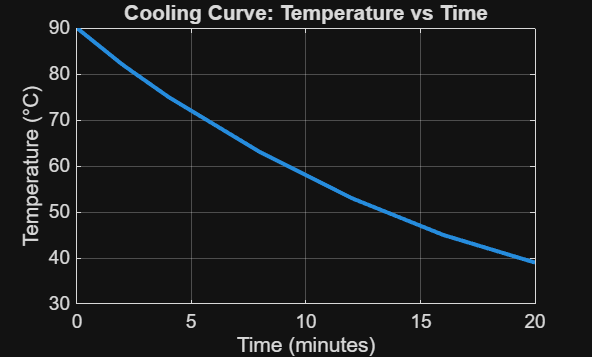

% Project 9

clc; clear; close all;

% 1. Create time vector (minutes)
t = 0:2:20;

% 2. Create a realistic decreasing temperature vector (°C)
% Example: cooling from 90°C down to ~30°C
T = [90 82 75 69 63 58 53 49 45 42 39];

% 3. Plot T vs t
figure;
plot(t, T, 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Temperature (°C)');
title('Cooling Curve: Temperature vs Time');
grid on;

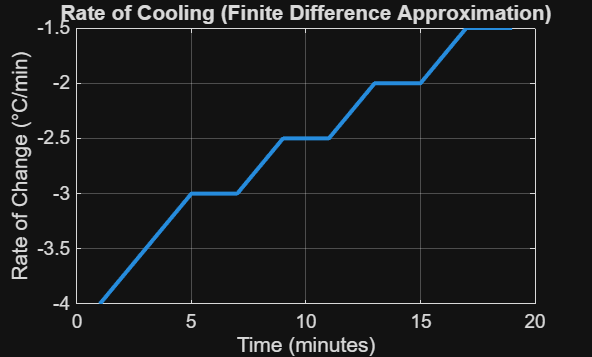


% 4. Estimate rate of change using finite differences
dTdt = diff(T) ./ diff(t);   % derivative approximation
t_mid = t(1:end-1) + diff(t)/2; % midpoint times for plotting

figure;
plot(t_mid, dTdt, 'LineWidth', 2);
xlabel('Time (minutes)');
ylabel('Rate of Change (°C/min)');
title('Rate of Cooling (Finite Difference Approximation)');
grid on;


% 5. Estimate total thermal exposure (area under curve)
thermal_exposure = trapz(t, T);

% Display result
fprintf('Total Thermal Exposure ≈ %.2f °C·min\n', thermal_exposure);

Total Thermal Exposure ≈ 1201.00 °C·min
